clc; clear; close all;
addpath('functions/');

n = 200;
x1 = 5;
v1 = 1;
t = 1;
sigmaA = 0.2;
sigmaN = 20;
q=0.2;

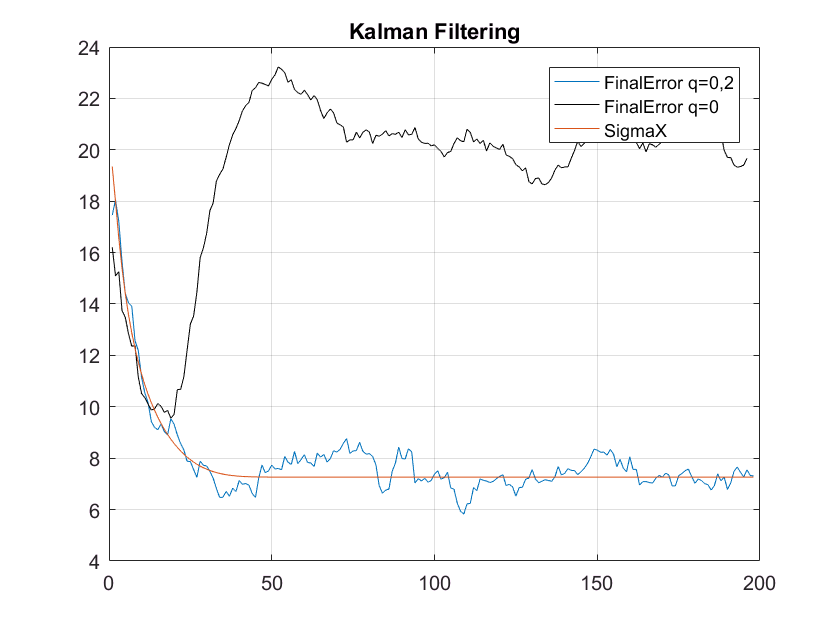

M=100;
ErrSum=zeros(1,n);

for i=1:M
    [ X, Xk, SigmaX ] = calcKalman( n, sigmaA, sigmaN, x1, v1, t, q);
    ErrCur = ( X(1,:) - Xk(1,:) ).^2;
    ErrSum = ErrSum + ErrCur;
end
FinalError = ( ErrSum(3:end)./(M-1) ).^0.5;

QErrSum=zeros(1,n);
for i=1:M
    [ QX, QXk, QSigmaX ] = calcKalman( n, sigmaA, sigmaN, x1, v1, t, 0);
    QErrCur = ( QX(1,:) - QXk(1,:) ).^2;
    QErrSum = QErrSum + QErrCur;
end
QFinalError = ( QErrSum(3:end)./(M-1) ).^0.5;

figure;
plot(FinalError);
hold on
plot(QFinalError(3:end),'black');
plot(SigmaX(3:end));
grid
legend('FinalError q=0,2','FinalError q=0','SigmaX');
title('Kalman Filtering');